# Testing the 1-Beam Purturbation Method

Version Info:

Version 1:

(04/20/2026)

MLX script for testing the 1-Beam version of the algorithm.

## Clear variables between Runs:

clear % clear variables and everything
clc % clear command window

## Set up Save Path

saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';
%if ~exist(saveDir, 'dir')
%    mkdir(saveDir);
%end

## Select Parameters:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
params.freq = 3e9;
params.lambda = 3e8 / params.freq; 
lambda = params.lambda; 
%params.N = 9;
%N = params.N; %Number of drones

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate


## Generate Initial Configuration (To serve as a starting point for our optimization)

% Initialize nieve 9-element "double cross" coordinates
%x = [0 0 0 0.5*lambda -0.5*lambda 0.5*lambda -0.5*lambda lambda -lambda]';
%y = [0 0.5*lambda -0.5*lambda 0 0 0.5*lambda -0.5*lambda lambda -lambda]';
    
% Initialize Daniil's "good" version of the 9-element "double cross" coordinates
%z = zeros(1,N);
%d1 = 0.422 * lambda;
%d2 = 0.554 * lambda;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize Eric's 'better' version (specifically for 120 degrees)
%d1 = 0.049553426571036;
%d2 = 0.049015017974167;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize test version with two elements
%x = [0 lambda/2];
%y = [0 0];

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];


% Initialize Eric's "true correct and optimal 9 element ones" from the meeting with everybody
% (double cross with two radii)
%x = [0	-0.042211347450806	0.042211347450806	0	0	0.039173549691350	-0.039173549691350	-0.039173549691350	0.039173549691350];
%y = [0	0	0	0.042211347450806	-0.042211347450806	0.039173549691350	0.039173549691350	-0.039173549691350	-0.039173549691350];

% Initialize Eric's 13 element coordinates
%x = [0 0.0150 0.0075 -0.0075 -0.0150 -0.0075 0.0075 0.0866 0.0000 -0.0866 -0.0866 -0.0000 0.0866];
%y = [0 0 0.0130 0.0130 0.0000 -0.0130 -0.0130 0.0500 0.1000 0.0500 -0.0500 -0.1000 -0.0500];

% Initialize test version without center emitter
%x(1) = [];
%y(1) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Compare 5, 9(ring), 13 element cases

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];

% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
% for 5 elements
%d1 = 0.019598444542977;
%d2 = 0.019598444542977;
% for 9 elements
%d1 = 0.5 * lambda;
%d2 = 0.5 * lambda;
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9) %Change to 5,9,13 apropriatly

x =          0    0.0488    0.0000   -0.0488   -0.0000    0.0345   -0.0345   -0.0345    0.0345


y =          0         0    0.0488    0.0000   -0.0488    0.0345    0.0345   -0.0345   -0.0345



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Eric's special calculated emitter positions (2/25/26)

% N=5
%x = [0	0.019598452160414	0.000000000000000	-0.019598452160414	-0.000000000000000];
%y = [0	0	0.019598452160414	0.000000000000000	-0.019598452160414];

%N=9
%x = [0	0.0505	0.0357	0.0000	-0.0357	-0.0505	-0.0357	-0.0000	0.0357];
%y = [0	0	0.035713085910583	0.050505930448942	0.035713085910583	0.000000000000000	-0.035713085910583	-0.050505930448942	-0.035713085910583];

%N=13
%x = [0	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662	-0.000000000000000	0.025300319574662	0.043821438951044];
%y = [0	0	0.025300319574662	0.043821438951044	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662];

%N=17
%x = [0	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899	-0.000000000000000	0.019364112741899	0.035780214854963	0.046749103604814];
%y = [0	0	0.019364112741899	0.035780214854963	0.046749103604814	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test multiples of geometric pattern
%x = (1.1)*x;
%y = (1.1)*y;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Single emitter for 9 elements
%A_single = [1, 1, 0, 0, 0, 0, 0, 0, 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Linear emitter for 9 elements
%x = linspace(-4,4,9).*(0.5*lambda);
%y = zeros(1,9);

## Set-up and Run the One-Beam version of the Algorithm

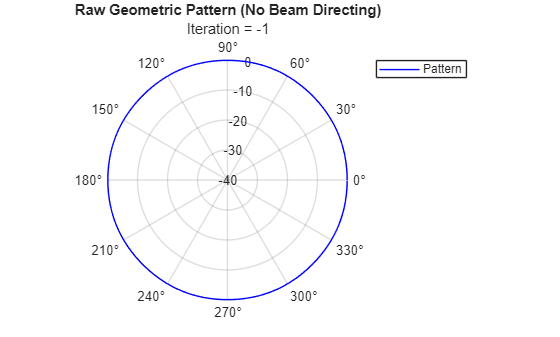

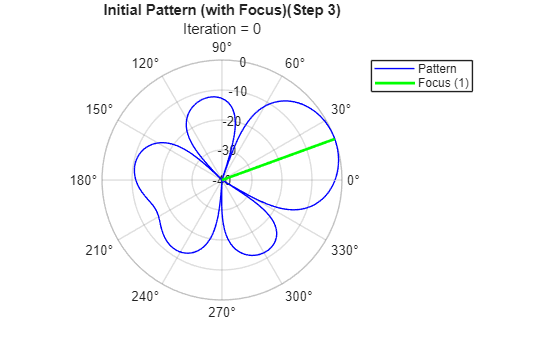

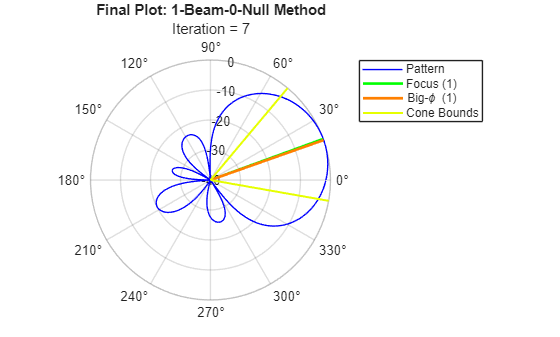

results1 = struct with fields:
                             final_epoch: 7
                         final_iteration: 7
                              total_time: 1.6276
                                       m: 0
                             focus_angle: 0.3491
                         focus_angle_deg: 20
                                cone_rad: 0.5236
                              null_angle: []
                          null_angle_deg: []
                      max_sidelobe_store: [41×1 double]
                      max_side_phi_store: [41×1 double]
                      main_peakLoc_store: [41×1 double]
                      main_peakVal_store: [41×1 double]
                          main_peak_skew: [41×1 double]
    directivity_metric_1_beamwidth_store: [41×1 double]
                          final_function: [5.2349 - 0.0000i 5.2685 - 0.0000i 5.3017 - 0.0000i 5.3345 - 0.0000i 5.3668 - 0.0000i 5.3987 - 0.0000i 5.4301 - 0.0000i 5.4610 - 0.0000i 5.4914 - 0.0000i 5.5213 - 0.0000i 5.5508

%% Start Function
Max_iter = 40; %The algithm goes to step maxiter
eps_dB = -20;
phi_0 = deg2rad(20);
null_phi_list = deg2rad([]);
save_plots = false;
save_final_plot = true;
cone_rad = deg2rad(30);


results1 = perturb_method_v23(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_plots', false, ...
    'show_plot_raw', true, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', false)





saveFile = fullfile(saveDir, 'single_angle_1beam.mat');
save(saveFile, ...
    'results1', ...
    'phi_0', ...
    'eps_dB', ...
    'Max_iter', ...
    'null_phi_list', ...
    'cone_rad');


## Plot Max Sidelobe vs. Epoch Number (1-Beam)

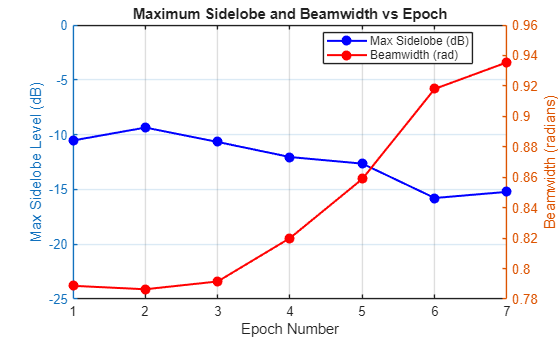

loadFile = fullfile(saveDir, 'single_angle_1beam.mat');
load(loadFile);

%% === Plot Maximum Sidelobe vs. Epoch ===

%{
% Extract the stored sidelobe values
sl_store = results1.max_sidelobe_store;

% Find the last valid entry (not NaN and not -Inf)
valid_mask = ~(isnan(sl_store) | isinf(sl_store));
last_valid = find(valid_mask, 1, 'last');

if isempty(last_valid)
    error('No valid sidelobe entries found in results1.max_sidelobe_store');
end

% Trim to valid portion
sl_valid = sl_store(1:last_valid);

% Epoch axis (1-based index)
epochs = 1:last_valid;

%% --- Make the plot ---
figure;
plot(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch');

%ylim([-40 0]);     % Same as polar plot
ylim([eps_dB-1 0]); % See wholw dB range
ylim([-120 0]); % eyeball it
xlim([1 last_valid]);
%}
%% === Plot Maximum Sidelobe, Beamwidth, and Focus Value vs Epoch ===

sl_store = results1.max_sidelobe_store;
bw_store = results1.directivity_metric_1_beamwidth_store;


% Determine valid entries
valid_mask = ~(isnan(sl_store) | isinf(sl_store));
last_valid = find(valid_mask, 1, 'last');

if isempty(last_valid)
    error('No valid sidelobe entries found in results1.max_sidelobe_store');
end

% Trim
sl_valid = sl_store(1:last_valid);
bw_valid = bw_store(1:last_valid);

epochs = 1:last_valid;

% Skip the first 5 points
Nskip = 0;

sl_valid = sl_valid(Nskip+1:end);
bw_valid = bw_valid(Nskip+1:end);
epochs   = epochs(Nskip+1:end);


%% ---- Make plot with dual y-axes ----
figure;

%% LEFT AXIS — Max Sidelobe (dB)
yyaxis left
plot(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
%scatter(epochs, sl_valid, 40, 'b', 'filled');
ylabel('Max Sidelobe Level (dB)');
ylim([eps_dB-5 0]);   % adjust as desired

%% RIGHT AXIS — Beamwidth (radians)
yyaxis right
plot(epochs, bw_valid, '-or', 'LineWidth', 1.5, 'MarkerFaceColor','r');
%scatter(epochs, bw_valid, 40, 'r', 'filled');
ylabel('Beamwidth (radians)');

%% Formatting
xlabel('Epoch Number');
title('Maximum Sidelobe and Beamwidth vs Epoch');
grid on;
xlim([1 last_valid]);

legend({'Max Sidelobe (dB)', 'Beamwidth (rad)'}, 'Location','best');


outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_Epoch_No_Null.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_Epoch_Null_90deg_cont.fig');

## Plot Max Sidelobe vs. SemiLog Epoch Number (1-Beam)

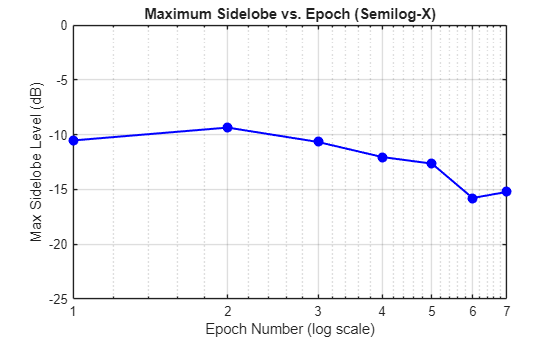

figure;
semilogx(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number (log scale)');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch (Semilog-X)');

ylim([eps_dB-5 0]);
xlim([1 last_valid]);

outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_LogEpoch_No_Null.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_EpochLog_Null_90deg_cont.fig');


## (Optional): Show Plot of Deep Run (1-Beam)

phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

bw = directivity_met_v2(phi_mesh, results1.final_function, phi_0)

bw = struct with fields:
    main_peak_angle: 0.3393
         peak_value: 6.2351
            left_05: 6.1454
           right_05: 0.8190
          beamwidth: 0.9567


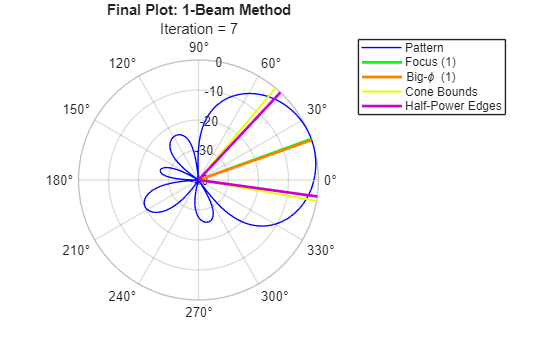


lab_1 = "Final Plot: 1-Beam Method";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                results1.final_function, ...
                'label',lab_1, ...
                'phi_0', phi_0, ...
                'phi_s', [], ...
                'Slobe', [], ...
                'null_phi', [] , ...
                'iter', results1.final_iteration, ...
                'show_plots', true, ...
                'cone_rad', results1.cone_rad, ...
                'bw_edges_right', bw.right_05,...
                'bw_edges_left', bw.left_05,...
                'Big_phi', results1.Big_phi_final);
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Plot_No_Null_V15.fig';
savefig( fullfile(outdir, fname) );

%savefig(gcf, 'Plot_Null_90deg_cont_1000_Iter.fig');

## Run a sweep over several Focus Angles for (1-Beam) version of the Method:

% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';


%% Sweep setup
Max_iter = 200;
eps_dB = -20;
%phi_0 = deg2rad(120);
focusAngles_deg = 0:1:360;   % Example sweep
%focusAngles_deg = 0:1:10;   % Example sweep
numAngles = numel(focusAngles_deg);
test_As = ones(numel(x),1);
%phi = linspace(0, 2*pi, 1000);   % MUST match algorithm
phi = linspace(0, 2*pi, 1000+1);
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);

F_final_store = NaN(numAngles, nPhi);   % magnitude
max_SL_all   = cell(numAngles, 1);   % cell array of sidelobe vectors
epochs_all   = zeros(numAngles, 1);  % store final epoch count
Big_phi_final = NaN(numAngles, 1); % store final  
right_bound   = NaN(numAngles, 1);  % store right half power beam bound
left_bound   = NaN(numAngles, 1);  % store left half power beam bound
main_peak_skew = zeros(numAngles, 1);  %store results for diffrence between main beam and focus angle
phi0_all_rad = deg2rad(focusAngles_deg);
badAngles = false(numAngles,1); % setup for recording bad angles

%% Sweep loop
for i = 1:numAngles
    try
        phi0 = phi0_all_rad(i);
        
        results = perturb_method_v20(Max_iter, eps_dB, x, y, phi0, ...
            'null_phi', [], ...
            'show_plots', false, ...
            'verbose', false, ...
            'const_null_update', false);

        fprintf('Sweep iter %d OK (%.1f deg)\n', i, focusAngles_deg(i));
        bw = directivity_met_v2(phi, results.final_function, phi0);

        % Store relevant data
        max_SL_all{i} = results.max_sidelobe_store;
        epochs_all(i) = results.final_epoch;
        F_at_focus(i) = results.F_at_phi_0;
        F_final_store(i, :) = results.final_function;
        Big_phi_final(i) = results.Big_phi_final;
        right_bound(i) = bw.right_05;
        left_bound(i) = bw.left_05;
        main_peak_skew(i) = results.main_peak_skew(results.final_epoch);
        % NOTE: Remember to double check the above for correct epoch.

    catch ME
        % ---- Mark as bad ----
        badAngles(i) = true;

        fprintf('*** Sweep iter %d FAILED at %.1f deg ***\n', ...
                 i, focusAngles_deg(i));
        fprintf('%s\n', ME.message);

        % ---- Fill safe defaults ----
        max_SL_all{i}       = NaN;
        epochs_all(i)      = NaN;
        F_at_focus(i)    = NaN;
        F_final_store(i,:) = NaN;
        right_bound(i) = NaN;
        left_bound(i) = NaN;

        continue;   
    end
end

Sweep iter 1 OK (0.0 deg)
Sweep iter 2 OK (1.0 deg)
Sweep iter 3 OK (2.0 deg)
Sweep iter 4 OK (3.0 deg)
Sweep iter 5 OK (4.0 deg)
Sweep iter 6 OK (5.0 deg)
Sweep iter 7 OK (6.0 deg)
Sweep iter 8 OK (7.0 deg)
Sweep iter 9 OK (8.0 deg)
Sweep iter 10 OK (9.0 deg)
Sweep iter 11 OK (10.0 deg)
Sweep iter 12 OK (11.0 deg)
Sweep iter 13 OK (12.0 deg)
Sweep iter 14 OK (13.0 deg)
Sweep iter 15 OK (14.0 deg)
Sweep iter 16 OK (15.0 deg)
Sweep iter 17 OK (16.0 deg)
Sweep iter 18 OK (17.0 deg)
Sweep iter 19 OK (18.0 deg)
Sweep iter 20 OK (19.0 deg)
Sweep iter 21 OK (20.0 deg)
Sweep iter 22 OK (21.0 deg)
Sweep iter 23 OK (22.0 deg)
Sweep iter 24 OK (23.0 deg)
Sweep iter 25 OK (24.0 deg)
Sweep iter 26 OK (25.0 deg)
Sweep iter 27 OK (26.0 deg)
Sweep iter 28 OK (27.0 deg)
Sweep iter 29 OK (28.0 deg)
Sweep iter 30 OK (29.0 deg)
Sweep iter 31 OK (30.0 deg)
Sweep iter 32 OK (31.0 deg)
Sweep iter 33 OK (32.0 deg)
Sweep iter 34 OK (33.0 deg)
Sweep iter 35 OK (34.0 deg)
Sweep iter 36 OK (35.0 deg)
Sweep iter 


%% Convert cell array → padded matrix

%% Trim each sidelobe vector to its actual recorded length
for i = 1:numAngles
    v = max_SL_all{i};

    % Valid sidelobes are real numbers between 0 and -200 dB
    validIdx = find(v <= 0 & v >= -200);

    if isempty(validIdx)
        max_SL_all{i} = -40;      % fallback
    else
        lastGood = validIdx(end);
        max_SL_all{i} = v(1:lastGood);
    end
end

%% Diagnostic: check sidelobe vector lengths for each angle
%{
fprintf("\n=== Sidelobe vector lengths per angle ===\n");
for i = 1:numAngles
    L = length(max_SL_all{i});
    fprintf("Angle %4.0f deg → length = %d\n", focusAngles_deg(i), length(max_SL_all{i}));
end
%}

% Find longest run (max epoch count)
maxLen = max( cellfun(@length, max_SL_all) );
%fprintf("\nMax sidelobe-store length = %d\n", maxLen);

% Preallocate with NaNs (which surf will skip)
SL_matrix = NaN(numAngles, maxLen);

for i = 1:numAngles
    L = length(max_SL_all{i});
    SL_matrix(i, 1:L) = max_SL_all{i};
end

%% === Extract final-epoch sidelobe for each angle ===
SL_final = zeros(numAngles,1);

for i = 1:numAngles
    v = max_SL_all{i};
    if isempty(v)
        SL_final(i) = NaN;    % should not happen, but safe
    else
        SL_final(i) = v(end); % final epoch sidelobe
    end
end

%% ---- Save sweep data ----
saveFile = fullfile(saveDir, 'sidelobe_sweep_1beam.mat');

save(saveFile, ...
    'SL_matrix', ...
    'max_SL_all', ...
    'SL_final', ...
    'focusAngles_deg', ...
    'epochs_all', ...
    'F_final_store', ...
    'phi', ...
    'badAngles', ...
    'maxLen', ...
    'eps_dB', ...
    'Max_iter', ...
    'right_bound', ...
    'left_bound', ...
    'main_peak_skew', ...
    'Big_phi_final');


## Waterfall Plots of dB vs. Epoch vs. Angle (1-Beam)

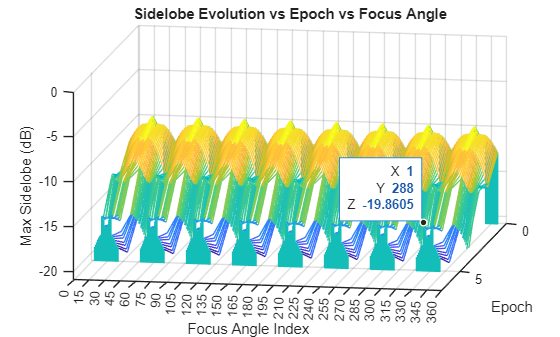

%% ---- Load previously saved data ----
% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';

loadFile = fullfile(saveDir, 'sidelobe_sweep_1beam.mat');
load(loadFile);

%% Waterfall Plot (best for seeing shape of many curves)
figure;
waterfall(SL_matrix);
xlabel('Epoch');
ylabel('Focus Angle Index');
zlabel('Max Sidelobe (dB)');
title('Sidelobe Evolution vs Epoch vs Focus Angle');

%yticks(1:numAngles);
%yticklabels(string(focusAngles_deg));

% Label only every 5 degrees
labelAngles = 0:15:360;

% Convert those angles to row indices in your sweep
labelIdx = arrayfun(@(a) find(focusAngles_deg == a, 1), labelAngles);

% Remove angles that do not exist exactly due to step size
valid = ~cellfun(@isempty, num2cell(labelIdx));
labelAngles = labelAngles(valid);
labelIdx     = labelIdx(valid);

% Apply ticks/labels
yticks(labelIdx);
yticklabels(string(labelAngles));

%% Compute global minimum sidelobe actually achieved (ignoring NaN)
globalMinSL = min(SL_matrix(:), [], 'omitnan');

% A small pad (e.g. 1 dB) so the lowest curve is visible
zlim([globalMinSL - 1, 0]); %try to set at just below dB threshold
xlim([0 maxLen+1]);
ylim([0 numAngles])
grid on;

ax = gca;
chart = ax.Children(1);
datatip(chart,9,360,-11.09);
view(45, 30); %Classic "from front-right"
view(30, 50); %More overhead (good for reading labels)
view(80, 25); %More from the side (good for depth)
view(100, 20); %Show epoch axis clearly

outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = '3D_Plot_No_Null.fig';
savefig( fullfile(outdir, fname) );

## Plot 2D Limit slice: Angle vs Skew  (1-Beam)

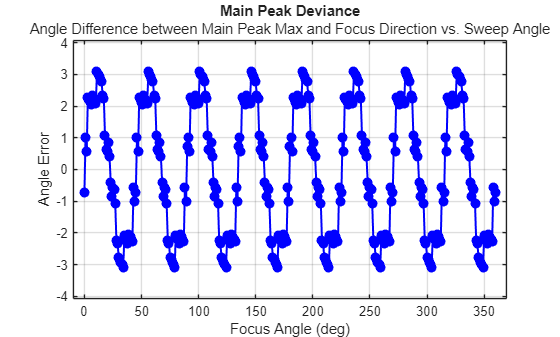

%% === Plot 2D slice: Angle vs Final Sidelobe ===
figure;
plot(focusAngles_deg, rad2deg(main_peak_skew), '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on;

xlabel('Focus Angle (deg)');
xlim([-10 370]);
ylabel('Angle Error');
ylim([min(rad2deg(main_peak_skew)) - 1, max(rad2deg(main_peak_skew)) + 1]);
%ylim([(-5) - 1, (5) + 1]);
title('Main Peak Deviance');
subtitle('Angle Difference between Main Peak Max and Focus Direction vs. Sweep Angle');

outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Skew_Behaviour_No_Null.fig';
savefig( fullfile(outdir, fname) );

## Plot 2D Limit slice: Angle vs Final Sidelobe  (1-Beam)

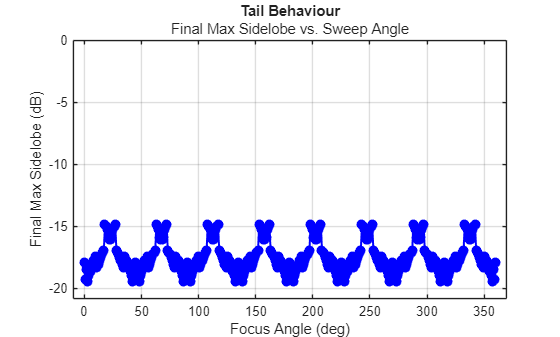

%% === Plot 2D slice: Angle vs Final Sidelobe ===
figure;
plot(focusAngles_deg, SL_final, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on;

xlabel('Focus Angle (deg)');
xlim([-10 370]);
ylabel('Final Max Sidelobe (dB)');
ylim([globalMinSL - 1, 0]);
title('Tail Behaviour');
subtitle('Final Max Sidelobe vs. Sweep Angle');

outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Tail_Behaviour_No_Null.fig';
savefig( fullfile(outdir, fname) );

## Plot: Angle vs Final Sidelobe vs Focus Magnitude  (1-Beam)

figure;
scatter3(focusAngles_deg, SL_final, F_at_focus, 40, F_at_focus, 'filled');

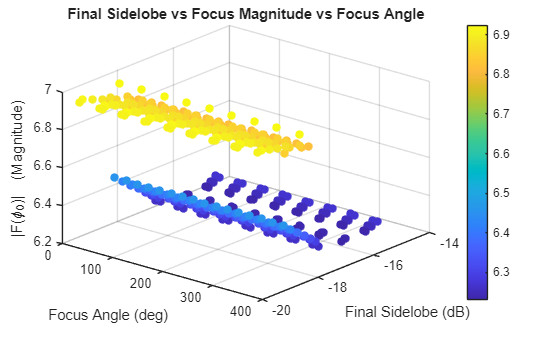


xlabel('Focus Angle (deg)');
ylabel('Final Sidelobe (dB)');
zlabel('|F(\phi_0)|  (Magnitude)');
title('Final Sidelobe vs Focus Magnitude vs Focus Angle');

grid on;
view(40, 30);
colorbar;

## Compare Double-Cross vs. Regular N-gon vs. Linear Geometry

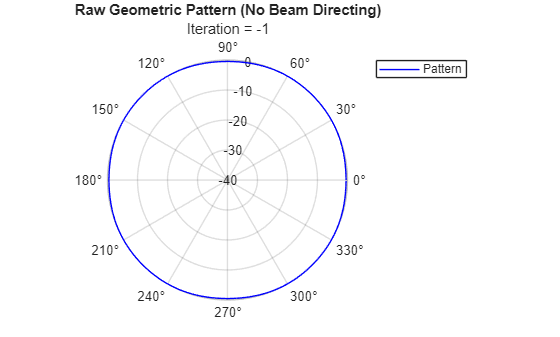

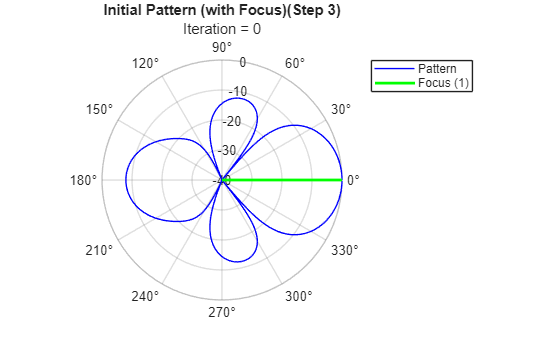

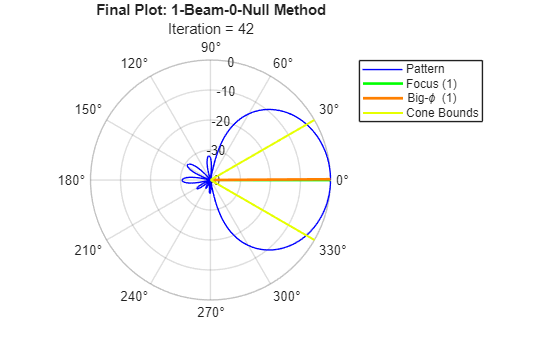

results1 = struct with fields:
                             final_epoch: 42
                         final_iteration: 42
                              total_time: 13.2011
                                       m: 0
                             focus_angle: 0
                         focus_angle_deg: 0
                                cone_rad: 0.5236
                              null_angle: []
                          null_angle_deg: []
                                 F_store: [401×1000 double]
                      max_sidelobe_store: [401×1 double]
                      max_side_phi_store: [401×1 double]
                      main_peakLoc_store: [401×1 double]
                      main_peakVal_store: [401×1 double]
                          main_peak_skew: [0 0 0 0.0188 0 0.0503 0.0188 0.0188 0.0126 0.0126 0.0126 -0.0063 -0.0063 -0.0126 -0.0063 -0.0063 0.0063 0.0063 0.0063 0.0188 0.0188 0.0188 0.0188 0.0188 0 0 0.0063 -0.0063 -0.0063 -0.0126 … ] (1×43 double)
    directivity_metri

%% Shared Base Variables
Max_iter = 400; %The algithm goes to step maxiter
eps_dB = -30;
phi_0 = deg2rad(0);
null_phi_list = deg2rad([]);
cone_rad = deg2rad(30);
N = 9;
phi = linspace(0, 2*pi, 1000+1);   % MUST match algorithm
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);

%% Double Cross Version
% Initialize Eric's 'better' 9-element version (specifically for 120 degrees)
d1 = 0.049553426571036;
d2 = 0.049015017974167;
[x,y] = d1d2Convert(d1,d2,N);

results1 = perturb_method_v22(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'show_plot_raw', false, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true)

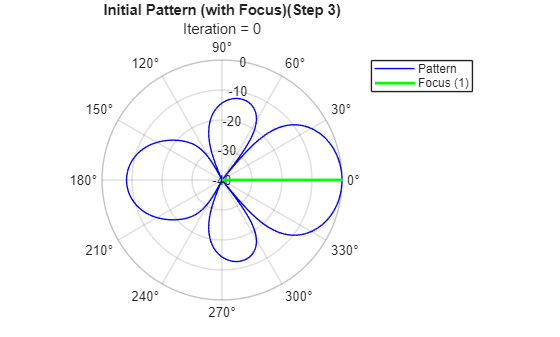

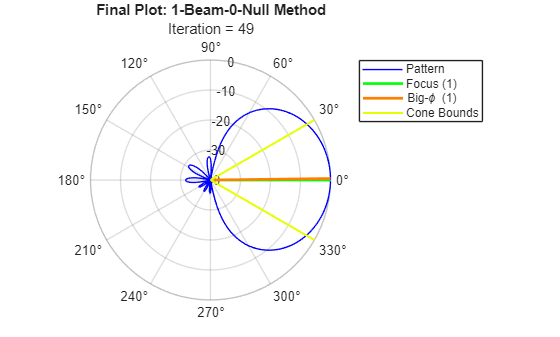


%% Regular N-gon Version
% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9); %Change to 5,9,13 apropriatly

results2 = perturb_method_v22(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'show_plot_raw', false, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true);

%{
 %% Linear Version:
% Test Linear emitter for 9 elements (along x-axis)
params.freq = 3e9;
params.lambda = 3e8 / params.freq; 
lambda = params.lambda; 
x = linspace(-4,4,9).*(2*lambda);
y = zeros(1,9);

results3 = perturb_method_v22(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'show_plot_raw', true, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true);

%}



%% Combine run data
%runs = {results1, results2, results3};
%labels = {"Double Cross", "Regular N-gon", "Linear"};
runs = {results1, results2};
labels = {"Double Cross", "Regular N-gon"};
Nruns = numel(runs);

%% Extract and Trim Data from Each Run
sl_all = cell(Nruns,1);
bw_all = cell(Nruns,1);
epochs_all = cell(Nruns,1);
F_focus_all = cell(Nruns,1);
F_focus_dB_all = cell(Nruns,1);
G_all = cell(Nruns,1);
A_eff_all = cell(Nruns,1);

for r = 1:Nruns

    res = runs{r}; % set target results

    sl_store = res.max_sidelobe_store;
    bw_store = res.directivity_metric_1_beamwidth_store;
    F_focus_store = res.focus_value_store;
    F_focus_dB_store = res.focus_value_store_dB;
    %G = function gain_calc(F_total, phi_mesh, phi0)
    %G_store = gain_calc(res.F_store, phi, phi_0);
    %G_store = gain_calc(res.F3D_store, phi, phi_0);
    G_store = res.G3D_store;
    A_eff_store = res.A_eff_store;

    % Determine valid entries
    valid_mask = ~(isnan(sl_store) | isinf(sl_store));
    %last_valid = find(valid_mask, 1, 'last');
    last_valid = min( Max_iter+1, find(valid_mask, 1, 'last') );

    if isempty(last_valid)
        error('Run %d has no valid sidelobe entries.', r);
    end

    % Trim
    sl_all{r} = sl_store(1:last_valid);
    bw_all{r} = bw_store(1:last_valid);
    F_focus_all{r} = F_focus_store(1:last_valid);
    F_focus_dB_all{r} = F_focus_dB_store(1:last_valid);
    epochs_all{r} = 1:last_valid;
    G_all{r} = G_store(1:last_valid);
    A_eff_all{r} = A_eff_store(1:last_valid); % May need to edit for null case

end

## Plot the comparison between versions (SL vs BW)

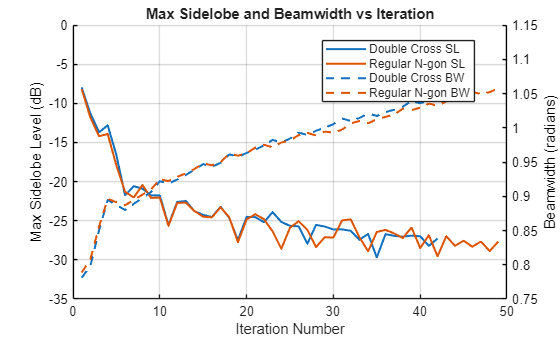


figure;

colors = lines(Nruns);   % automatic distinct colors

%% LEFT AXIS — Max Sidelobe
yyaxis left
hold on

for r = 1:Nruns
    plot(epochs_all{r}, sl_all{r}, '-', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Max Sidelobe Level (dB)');
ylim([eps_dB-5 0]);

%% RIGHT AXIS — Beamwidth
yyaxis right
hold on

for r = 1:Nruns
    plot(epochs_all{r}, bw_all{r}, '--', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Beamwidth (radians)');

%% Formatting
xlabel('Iteration Number');
title('Max Sidelobe and Beamwidth vs Iteration');
grid on;

legendStrings = strings(1,2*Nruns);

for r = 1:Nruns
    legendStrings(r) = labels{r} + " SL";
    legendStrings(r+Nruns) = labels{r} + " BW";
end

%% Make the y-axes black
ax = gca;
ax.YAxis(1).Color = 'k';   % left axis black
ax.YAxis(2).Color = 'k';   % right axis black

legend(legendStrings,'Location','best');


%% Save Figure Results
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Geometry_Comparison_SL_BW_vs_Epoch.fig';
savefig(fullfile(outdir, fname));


## Plot the comparison between versions (SL vs Coefficient Norm)

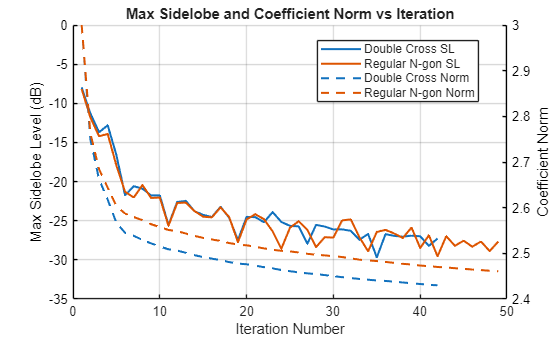


figure;

colors = lines(Nruns);   % automatic distinct colors

%% LEFT AXIS — Max Sidelobe
yyaxis left
hold on

for r = 1:Nruns
    plot(epochs_all{r}, sl_all{r}, '-', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Max Sidelobe Level (dB)');
ylim([eps_dB-5 0]);

%% RIGHT AXIS — Beamwidth
yyaxis right
hold on

for r = 1:Nruns
    norms = cellfun(@(a) sqrt(sum(abs(a).^2)), A_eff_all{r});
    plot(epochs_all{r}, ...
        norms, ...
        '--', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Coefficient Norm');

%% Formatting
xlabel('Iteration Number');
title('Max Sidelobe and Coefficient Norm vs Iteration');
grid on;

legendStrings = strings(1,2*Nruns);

for r = 1:Nruns
    legendStrings(r) = labels{r} + " SL";
    legendStrings(r+Nruns) = labels{r} + " Norm";
end

%% Make the y-axes black
ax = gca;
ax.YAxis(1).Color = 'k';   % left axis black
ax.YAxis(2).Color = 'k';   % right axis black

legend(legendStrings,'Location','best');


%% Save Figure Results
%outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
%fname = 'Geometry_Comparison_SL_CNorm_vs_Epoch.fig';
%savefig(fullfile(outdir, fname));

## Plot the comparison between versions (SL vs Focus Value)

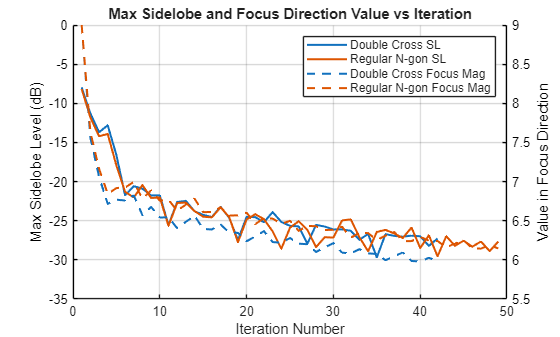


figure;

colors = lines(Nruns);   % automatic distinct colors

%% LEFT AXIS — Max Sidelobe
yyaxis left
hold on

for r = 1:Nruns
    plot(epochs_all{r}, sl_all{r}, '-', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Max Sidelobe Level (dB)');
ylim([eps_dB-5 0]);

%% RIGHT AXIS — Focus Value
yyaxis right
hold on

for r = 1:Nruns
    plot(epochs_all{r}, F_focus_all{r}, '--', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Value in Focus Direction');

%% Formatting
xlabel('Iteration Number');
title('Max Sidelobe and Focus Direction Value vs Iteration');
grid on;

legendStrings = strings(1,2*Nruns);

for r = 1:Nruns
    legendStrings(r) = labels{r} + " SL";
    legendStrings(r+Nruns) = labels{r} + " Focus Mag";
end

%% Make the y-axes black
ax = gca;
ax.YAxis(1).Color = 'k';   % left axis black
ax.YAxis(2).Color = 'k';   % right axis black

%legend(legendStrings,'Location','best');
%legend(legendStrings,'Location','southoutside');
legend(legendStrings,'Location','northeast');

%legend(legendStrings,'Location','east');

%% Save Figure Results
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Geometry_Comparison_SL_FD_vs_Epoch.fig';
savefig(fullfile(outdir, fname));

## Plot the comparison between versions (SL vs (3D) Focus Gain)

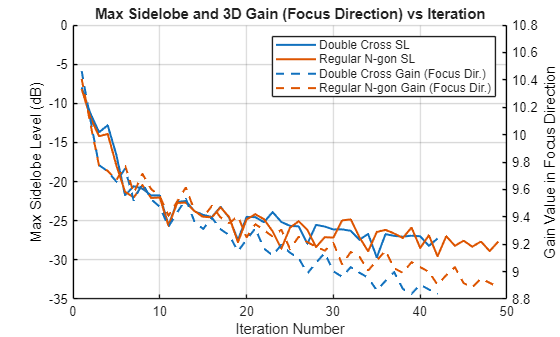

%% Function to calculate Gain
%{
G = function gain_calc(F_total, phi_mesh, phi0)
    % input the calculated f_total, the phi_mesh, and the target direction
    % phi0 to calculate Gain in that direction.
    
    I = trapz(phi_mesh, abs(F_total).^2);
    F_at_phi_0 = interp1(phi, F_total, phi_0, 'linear', 'extrap');
    G = 10*log((F_at_phi_0.^2 * 4*pi)/I);

end
%}


figure;

colors = lines(Nruns);   % automatic distinct colors

%% LEFT AXIS — Max Sidelobe
yyaxis left
hold on

for r = 1:Nruns
    plot(epochs_all{r}, sl_all{r}, '-', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Max Sidelobe Level (dB)');
ylim([eps_dB-5 0]);

%% RIGHT AXIS — Gain Value n Focus Direction
yyaxis right
hold on

for r = 1:Nruns
    %G = function gain_calc(F_total, phi_mesh, phi0)
    plot(epochs_all{r}, ...
        G_all{r}, ...
        '--', 'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Gain Value in Focus Direction');

%% Formatting
xlabel('Iteration Number');
title('Max Sidelobe and 3D Gain (Focus Direction) vs Iteration');
grid on;

legendStrings = strings(1,2*Nruns);

for r = 1:Nruns
    legendStrings(r) = labels{r} + " SL";
    legendStrings(r+Nruns) = labels{r} + " Gain (Focus Dir.)";
end

%% Make the y-axes black
ax = gca;
ax.YAxis(1).Color = 'k';   % left axis black
ax.YAxis(2).Color = 'k';   % right axis black

%legend(legendStrings,'Location','best');
%legend(legendStrings,'Location','southoutside');
legend(legendStrings,'Location','northeast');


%% Save Figure Results
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Geometry_Comparison_SL_3DGain_vs_Epoch.fig';
savefig(fullfile(outdir, fname));


## Compare Final Gains

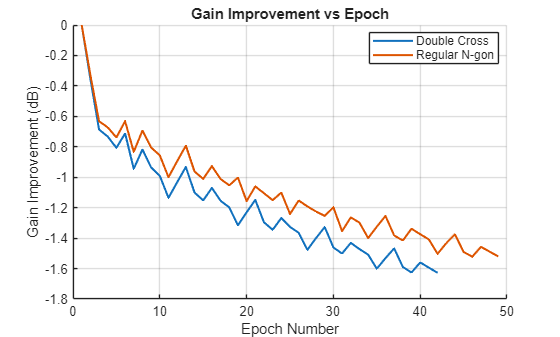

%{
figure; hold on;

for r = 1:Nruns
    G0 = G_all{r}(1);
    plot(epochs_all{r}, G_all{r} - G0, '-', ...
        'LineWidth', 1.5);
end

xlabel('Epoch Number');
ylabel('Gain Improvement (dB)');
title('Gain Improvement vs Epoch');
grid on;

legend(labels, 'Location','best');

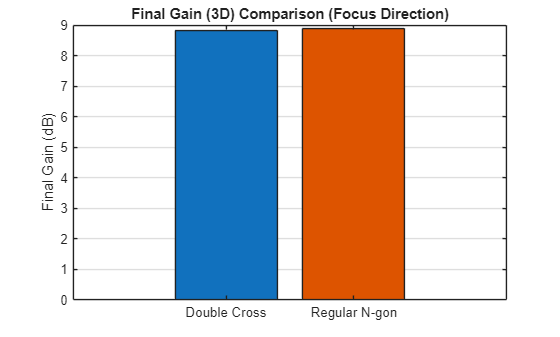

%}

G_final = zeros(Nruns,1);

for r = 1:Nruns
    G_final(r) = runs{r}.final_gain3D;
end

figure;
b = bar(G_final);
% Enable per-bar coloring
b.FaceColor = 'flat';

% Assign colors
colors = lines(Nruns);
b.CData = colors;

set(gca, 'XTickLabel', labels);
ylabel('Final Gain (dB)');
title('Final Gain (3D) Comparison (Focus Direction)');
%legend(labels, 'Location','northoutside','Orientation','horizontal');
grid on;

## Plot the comparison between versions (SL vs (Focus dB))

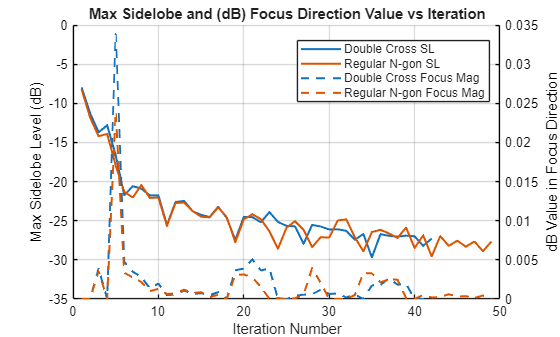


figure;

colors = lines(Nruns);   % automatic distinct colors

%% LEFT AXIS — Max Sidelobe
yyaxis left
hold on

for r = 1:Nruns
    plot(epochs_all{r}, sl_all{r}, '-', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('Max Sidelobe Level (dB)');
ylim([eps_dB-5 0]);

%% RIGHT AXIS — Focus Value
yyaxis right
hold on

for r = 1:Nruns
    plot(epochs_all{r}, F_focus_dB_all{r}, '--', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('dB Value in Focus Direction');

%% Formatting
xlabel('Iteration Number');
title('Max Sidelobe and (dB) Focus Direction Value vs Iteration');
grid on;

legendStrings = strings(1,2*Nruns);

for r = 1:Nruns
    legendStrings(r) = labels{r} + " SL";
    legendStrings(r+Nruns) = labels{r} + " Focus Mag";
end

%% Make the y-axes black
ax = gca;
ax.YAxis(1).Color = 'k';   % left axis black
ax.YAxis(2).Color = 'k';   % right axis black

legend(legendStrings,'Location','best');

%legend(legendStrings,'Location','southoutside');
%legend(legendStrings,'Location','northeast');
%legend(legendStrings,'Location','east');

%% Save Figure Results
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Geometry_Comparison_SL_FDdB_vs_Epoch.fig';
savefig(fullfile(outdir, fname));


## Plot the comparison between versions (SL vs (Focus dB))

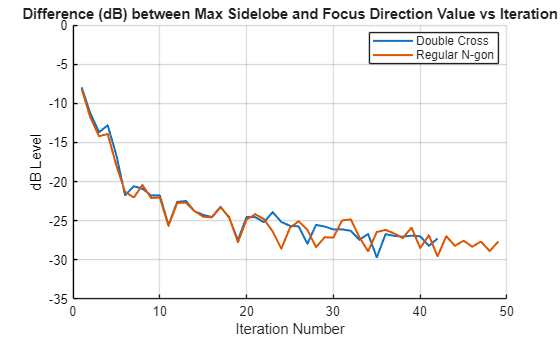


figure;

colors = lines(Nruns);   % automatic distinct colors

%% LEFT AXIS — Max Sidelobe
%yyaxis left
hold on

for r = 1:Nruns
    plot(epochs_all{r}, ...
        sl_all{r}-F_focus_dB_all{r}, ...
        '-', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('dB Level');
ylim([eps_dB-5 0]);

%% RIGHT AXIS — Focus Value
%{
yyaxis right
hold on

for r = 1:Nruns
    plot(epochs_all{r}, F_focus_dB_all{r}, '--', ...
        'Color', colors(r,:), ...
        'LineWidth', 1.5);
end

ylabel('dB Value in Focus Direction');
%}

%% Formatting
xlabel('Iteration Number');
title('Difference (dB) between Max Sidelobe and Focus Direction Value vs Iteration');
grid on;

legendStrings = strings(1,Nruns);

for r = 1:Nruns
    legendStrings(r) = labels{r} ;
    %legendStrings(r+Nruns) = labels{r} ;
end

%% Make the y-axes black
ax = gca;
ax.YAxis(1).Color = 'k';   % left axis black
%ax.YAxis(2).Color = 'k';   % right axis black

legend(legendStrings,'Location','best');

%legend(legendStrings,'Location','southoutside');
%legend(legendStrings,'Location','northeast');
%legend(legendStrings,'Location','east');

%% Save Figure Results
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Geometry_Comparison_SL_FD_Diff_vs_Epoch.fig';
savefig(fullfile(outdir, fname));
